# סדנה מטלב

יבגני קולונסקי, 2024, v0.1

## מה היא תוכנה מטלב

תוכנה המאפשרת טיפול קל ונוח במטריצות, שימוש בפונקציות ובנתונים, מימוש אלגוריתמים על נתונים ויצירת קשר עם תוכנות הכתובות בשפות אחרות.

## מטרות

- לכתוב ולשמור קוד פשוט ב-מטלב

- לבצע חישובים פשוטים ולשמור אתהתוצאות בקובץ

- ליצור גרף ולשמור אותוכ תמונה

- לבצע התאמה מדידות לפונקציה ןלחלץ ניתונים סטטיסטיים מהפלט

## **יצירת וקטורים**


$$v=\left\lbrack x_1 \;x_2 \;\ldotp \ldotp \ldotp x_n \right\rbrack$$


% creates row vector with components x1 .. xn
v = [5 1 7 9] 

v =      5     1     7     9


% first component: v(1). 
% Last component:  v(end)
v(1), v(end)

ans = 5

ans = 9


$$v=\left(x_1 :\Delta x:x_2 \right)$$


% creates vector from x1 to x2 with increments delta x
v = (0:2:6) 

v =      0     2     4     6



$$v=\textrm{linspace}\left(x_1 ,x_2 ,n\right)$$


% creates vector from x1 to x2 with length n
v = linspace(0, 6, 4)

v =      0     2     4     6


m = zeros(2,3)

m =      0     0     0
     0     0     0


m = ones(3,2)

m =      1     1
     1     1
     1     1


## תרגיל

אליס מדדה את מיקומו של כדור בנפילה חופשית במשך 12 שניות ואלו התוצאות:

### צרו וקטור עבור כל פרמטר שנמדד (x  ו- t)

t = (0:1:12);
x = [0 4.8 19.7 44.2 78.3 122.5 176.4 240.1 313.7 397 489.9 592.8 705.6]

x =          0    4.8000   19.7000   44.2000   78.3000  122.5000  176.4000  240.1000  313.7000  397.0000  489.9000  592.8000  705.6000


##  לולאות

**For** - runs known number of cycles

% for cycle example
vector = zeros(4,1);
for index = 1:4
    vector(index) = index^2;
end
vector

vector =      1
     4
     9
    16


**While** - runs while condition is true

% while cycle example
index = 1;
while (index < 5)
    vector(index) = index/2;
    index = index + 1;
end
vector

vector =     0.5000
    1.0000
    1.5000
    2.0000


## Vector operations

vector1 = [1 2 4];
vector2 = [4 6 8];
constant = 2;
% sum vectors
vector1 + vector2

ans =      5     8    12


% vector multiplied by constant
vector1 * constant

ans =      2     4     8


% vector multiplied by vector
vector1 .* vector2

ans =      4    12    32


% vector divided by vector
vector1 ./ vector2

ans =     0.2500    0.3333    0.5000


% length of vector
length(vector1)

ans = 3

% differenсies


$${\textrm{dx}}_i =x_{i+1} -x_i$$


diff(vector1)

ans =      1     2


$\frac{\Delta \;x}{\Delta \;t}=\frac{x_{i+n} -x_{i-n} }{t_{i+n} -t_{i-n} }$,  

n = 2;
deltax = x(1+2* n : end) - x(1 :  end - 2* n);
deltat = t(1+2*n : end) - t(1 :  end - 2*n);
v = deltax ./ deltat

v =    19.5750   29.4250   39.1750   48.9750   58.8500   68.6250   78.3750   88.1750   97.9750


##  תרגיל

### צרו וקטור של מהירות ממוצעת


$$v_i =\frac{x_{i+1} -x_i }{t_{i+1} -t_i }$$


% with cycles 
% ..
% or with one command
dx = diff(x)

dx =     4.8000   14.9000   24.5000   34.1000   44.2000   53.9000   63.7000   73.6000   83.3000   92.9000  102.9000  112.8000


dt = diff(t)

dt =      1     1     1     1     1     1     1     1     1     1     1     1


v = dx ./ dt

v =     4.8000   14.9000   24.5000   34.1000   44.2000   53.9000   63.7000   73.6000   83.3000   92.9000  102.9000  112.8000


Velocity $v_i$ correspondes to the midpoints of the intervals $\left\lbrack t_i \;\ldotp \ldotp t_{i+1} \right\rbrack :$


$${t_i }^{\prime } =t_i +\frac{t_{i+1} -t_i }{2}=t_i +\Delta t_i \;/\;2,\;\;\;i=1\;\ldotp \ldotp \ldotp n-1$$


t1 = t(1:end-1) + dt/2;

## שמירה

## תרגיל

שמרו את הווקטורים t, x, v

## גרפים

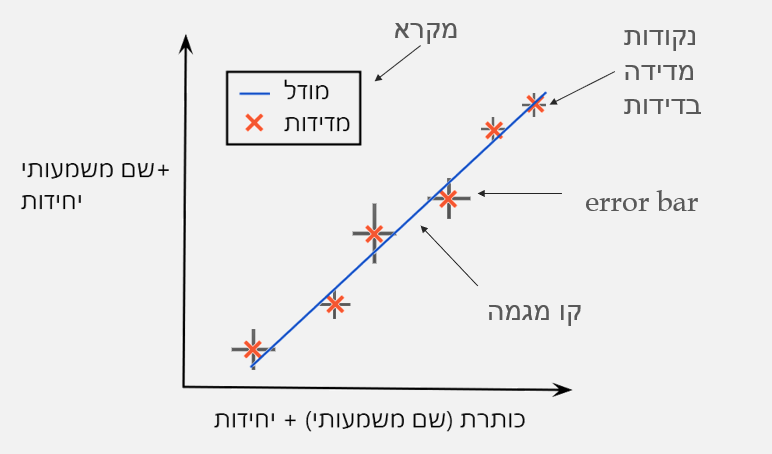

האיבר הראשון (t) מייצג את הפרמטר בציר האופקי.

האיבר השני (x) מייצג את הפרמטר של הציר האנכי.

האות r בוחרת כי הגרף יהיה בצע אדום, האות o בוחר את צורת הסמן.

הערה: במידה ולא נגדיר צבע וסמן, מטלב יבחר צבע בעצמו ויצייר קו רציף.

## תרגיל: 

צרו גרף של מיקום הכדור כפונקציה של הזמן. 

כך שהסמנים הם ירוקים בצור**ת +.**

t = (0:1:12);
x = [0 4.8 19.7 44.2 78.3 122.5 176.4 240.1 313.7 397 489.9 592.8 705.6]

x =          0    4.8000   19.7000   44.2000   78.3000  122.5000  176.4000  240.1000  313.7000  397.0000  489.9000  592.8000  705.6000


figure(1)
plot(t, x, 'b+')
xlabel('Time [s]')
ylabel('Ball coordinate [m]')
grid on;

לבחירת שם הציר האופקי  והציר האני, להוספת רשת

לשמירת קובץ שניתן לפתוח במטלב ולהמשיך את עריכת הגרף.

savefig('x(t).fig')

לשמירת קובץ תמונה אותנו ניתן לשים אחר כך בדו"ח.

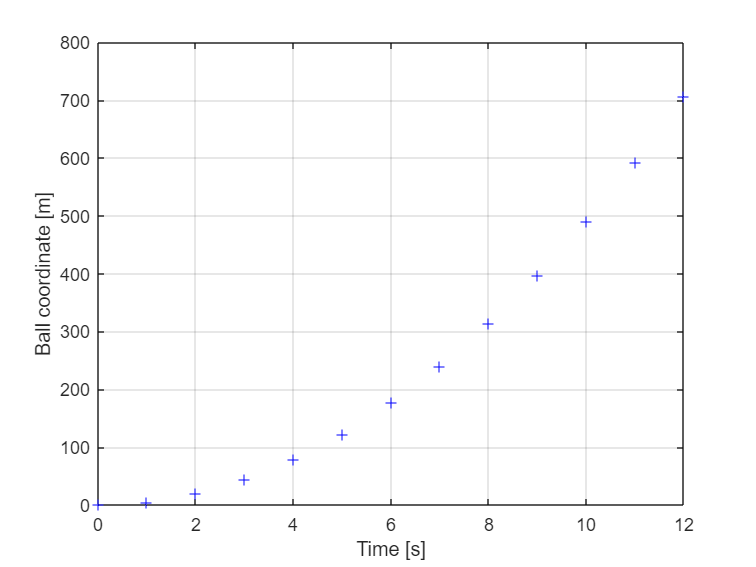

saveas(figure(1) ,'x(t).png' , 'png')

## **התאמת מדידות לפונקציה**

## תרגיל

בצעו התאמה של המדידות של אליס לפונקציה של נפילה חופשית ובדקו האם התאוצה תואמת את התיאוריה.

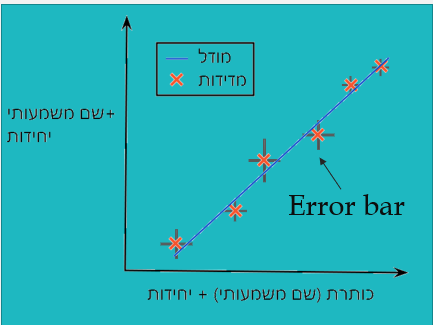

## Error bars and model fit

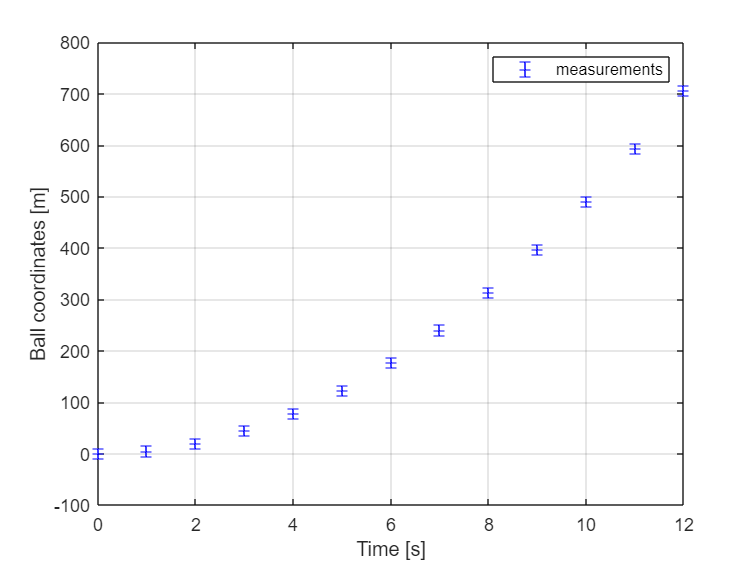

xerror = ones(1,13) * 10;
t = (0:1:12);
x = [0 4.8 19.7 44.2 78.3 122.5 176.4 240.1 313.7 397 489.9 592.8 705.6];


errorbar(t, x, xerror, 'b+');
legend('measurements');
grid on
xlabel('Time [s]');
ylabel('Ball coordinates [m]');

פעולות איבר-איבר, טרנספוז, end,  (:)

a = [1 2 3];
a'

ans =      1
     2
     3


b = [4 5 6];
a .* b

ans =      4    10    18


כתיבת וקטור עמודה /וקטור שורה

a = [1;2;3]

a =      1
     2
     3


שרשור וקטורים

% vector concatenation
a = [1 2 3];
b = [4 5 6];
c = [a b]

c =      1     2     3     4     5     6


כתיבת הערות (comments %)

 שורה בפונקצי  (..ירידת.).

a = [1 2 3 ...
    4 5 6]

a =      1     2     3     4     5     6


ניהול script sections והרצה שלהם. הרצה של חלק מהקוד F9.

שימוש בhelp F1, mathworks

מחיקת איבר מווקטור

a=[1,2,3,4,5];
% If you want to get rid of all cases where a is exactly equal to 3
b = a(a~=3)

b =      1     2     4     5


% If you want to delete the third element
b = a;
b(3)=[]

b =      1     2     4     5


% or on a single line
b = a([1:2, 4:end])

b =      1     2     4     5


 fitlm (הדפסה וללא הדפסה, גישה לתוצאות)

t = (0:1:12)

t =      0     1     2     3     4     5     6     7     8     9    10    11    12


x = [0 5 20 50 80 130 200 240 310 400 490 600 700]

x =      0     5    20    50    80   130   200   240   310   400   490   600   700


t2 = t .* t;
mdl = fitlm(t2, x)

mdl = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)     4.5197       3.0262    1.4935       0.16343
    x1              4.8711     0.044284       110    4.3832e-18


Number of observations: 13, Error degrees of freedom: 11
Root Mean Squared Error: 7.44
R-squared: 0.999,  Adjusted R-Squared: 0.999
F-statistic vs. constant model: 1.21e+04, p-value = 4.38e-18

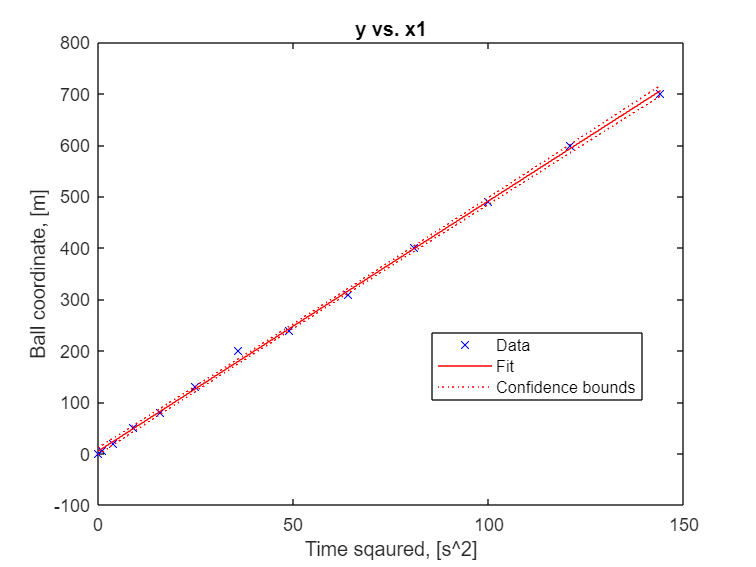

plot(mdl)
xlabel('Time sqaured, [s^2]')
ylabel('Ball coordinate, [m]')

mdl.Coefficients

ans = 2×4 table
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)     4.5197       3.0262    1.4935       0.16343
    x1              4.8711     0.044284       110    4.3832e-18


שמירה של cfit וגישה לתוצאות

work space, command line

פקודות מתמטיות:  

 length size abs sqrt, exp, log, 3e-23, min max mean std find findpeaks,sum,cumsum,diff,cos atan 

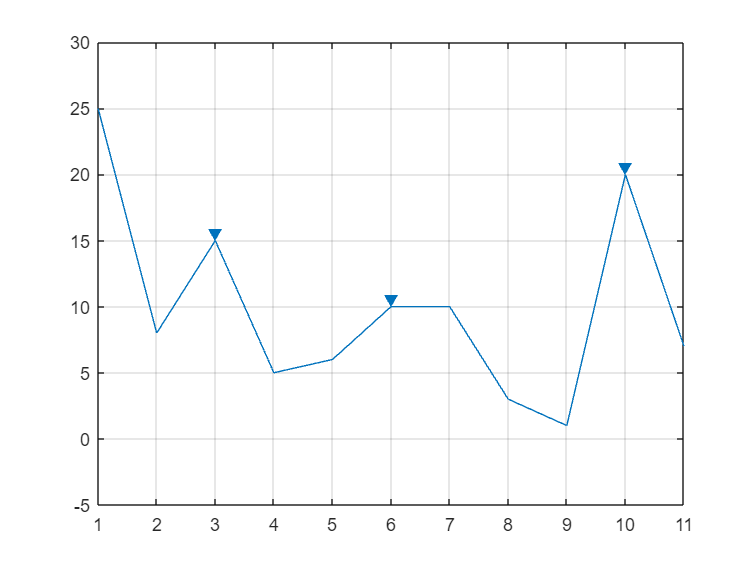

data = [25 8 15 5 6 10 10 3 1 20 7];
findpeaks(data)

length(data)

ans = 11

size(data)

ans =      1    11


 errorbarxy

loglog

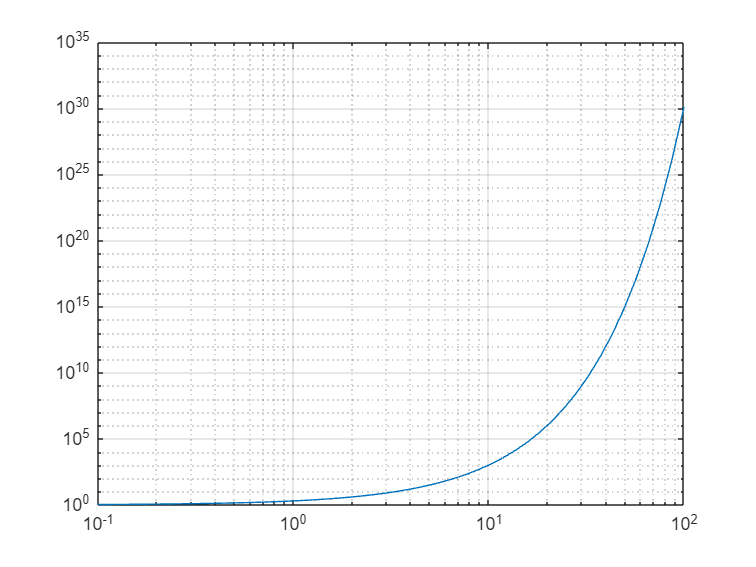

figure
x = logspace(-1,2);
y = 2.^x;
loglog(x,y)
grid on

  xlsread

legend

 hold on 

grid on

grid minor

title 

clear clc 

db

כניסה לתיעוד של פונקציה (ctrl+D)

עריכת figure ידנית

מציאת נקודה ב-figure  ופעולות  zoom

טעינת נתונים, פתיחתscripts 

שגיאות שמטלב מקפיץ ופיענוח שלהן

a = 22.4 ;
if (a/10)  == 2.24
    answ = 'true';
else
    answ = 'false';
end

MathWorks Support Team  on 9 Aug 2019

This behavior is because of floating point rounding errors which is inherent to the nature of floating point number representation and is not a bug. MATLAB uses IEEE 754 standard to represent floating point numbers and since limited number of bits are available to represent a number, larger the value gets, more will be the rounding errors in representing it.

MATLAB has a function called 'eps' which takes in a number and gives the difference between the given number and the next re-presentable number. To get more insight on how 'eps' is related to rounding errors, please refer to this link - [https://www.mathworks.com/help/matlab/matlab_prog/floating-point-numbers.html#f2-98690](https://www.mathworks.com/help/matlab/matlab_prog/floating-point-numbers.html#f2-98690)

In the example you provided, the 'eps' value of 2^1000 is 2.3792e+285 which indicates that the rounding errors will be of similar magnitude as well and hence you are getting unexpected results using mean. (Additional explanation can be found at the end of post)

In case you want to work with accurate representation of numbers, you can use the Symbolic Math Toolbox. For more information, refer to [https://www.mathworks.com/help/symbolic/create-symbolic-numbers-variables-and-expressions.html#buyfu27](https://www.mathworks.com/help/symbolic/create-symbolic-numbers-variables-and-expressions.html#buyfu27)

eps(22.4/10)

ans = 4.4409e-16

eps(2.24)

ans = 4.4409e-16

eps(0)

ans = 4.9407e-324